% NPP与海洋热浪关联分析（修复基准期计算问题）
% 分析2015-2024年热浪期间和非热浪期间的NPP异常

%clear;
%close all;
%clc;

%% 参数设置
lon_range = [110, 180]; % 东经110-180度
lat_range = [30, 60];  % 北纬30-60度
target_years = 2015:2024;  % 分析年份

% 文件路径
npp_data_folder = 'F:\NPP'; % NPP数据文件夹路径
hw_events_dir  = 'D:\dlb\m_mhw1.0-master\m_mhw1.0-master\data\global\marine_heatwave_results\'; % 热浪事件文件路径
output_dir = 'npp_heatwave_analysis'; % 输出目录

% 创建输出目录
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

fprintf('开始NPP与海洋热浪关联分析...\n');

开始NPP与海洋热浪关联分析...



%% 第一步：读取NPP数据
fprintf('读取NPP数据...\n');

读取NPP数据...



% 检查NPP数据文件夹是否存在
if ~isfolder(npp_data_folder)
    error('NPP数据文件夹不存在: %s\n请检查文件夹路径是否正确。', npp_data_folder);
end

% 获取NPP文件列表
npp_files = dir(fullfile(npp_data_folder, '*.hdf'));
if isempty(npp_files)
    error('在文件夹 %s 中找不到NPP数据文件', npp_data_folder);
end

fprintf('找到 %d 个NPP数据文件\n', length(npp_files));

找到 876 个NPP数据文件



% 解析文件名中的日期信息
file_dates = [];
file_years_data = [];  % 重命名避免冲突
file_months_data = []; % 重命名避免冲突
file_doy_data = [];    % 添加年积日信息

for i = 1:length(npp_files)
    filename = npp_files(i).name;
    
    % 提取年份和儒略日（根据实际文件名格式调整）
    year_str = filename(6:9);  % 假设格式为 'vgpm.YYYYDDD.hdf'
    doy_str = filename(10:12);
    
    year_val = str2double(year_str);  % 重命名避免冲突
    doy = str2double(doy_str);
    
    if isnan(year_val) || isnan(doy)
        continue;
    end
    
    file_date = datetime(year_val, 1, 1) + days(doy - 1);
    file_dates = [file_dates; file_date];
    file_years_data = [file_years_data; year_val];
    file_months_data = [file_months_data; month(file_date)];
    file_doy_data = [file_doy_data; doy];
end

% 按日期排序
[file_dates, sort_idx] = sort(file_dates);
file_years_data = file_years_data(sort_idx);
file_months_data = file_months_data(sort_idx);
file_doy_data = file_doy_data(sort_idx);
npp_files = npp_files(sort_idx);

% 读取第一个文件以获取数据维度
first_file = fullfile(npp_data_folder, npp_files(1).name);
try
    npp_data = hdfread(first_file, 'npp');
    [nlat, nlon] = size(npp_data);
    
    % 读取或创建经纬度信息
    try
        longitude = double(hdfread(first_file, 'Longitude'));
        latitude = double(hdfread(first_file, 'Latitude'));
        
        % 确保维度正确
        if size(longitude, 1) == 1 || size(longitude, 2) == 1
            [longitude, latitude] = meshgrid(longitude, latitude);
        end
        
        % 确保纬度从北到南递减
        if latitude(1,1) < latitude(end,1)
            latitude = flipud(latitude);
        end
    catch
        % 如果无法读取经纬度，创建假设的坐标
        longitude = linspace(-180, 180, nlon);
        latitude = linspace(90, -90, nlat);
        [longitude, latitude] = meshgrid(longitude, latitude);
    end
catch ME
    error('无法读取NPP数据: %s', ME.message);
end

% 裁剪研究区域
in_region = (latitude >= lat_range(1) & latitude <= lat_range(2)) & ...
            (longitude >= lon_range(1) & longitude <= lon_range(2));
[row_idx, col_idx] = find(in_region);
min_row = min(row_idx);
max_row = max(row_idx);
min_col = min(col_idx);
max_col = max(col_idx);

lat_region = latitude(min_row:max_row, min_col:max_col);
lon_region = longitude(min_row:max_row, min_col:max_col);

[nlat_region, nlon_region] = size(lat_region);

% 选择2015-2024年的数据
date_mask = file_years_data >= 2015 & file_years_data <= 2024;
selected_dates_npp = file_dates(date_mask);
selected_years_npp = file_years_data(date_mask);
selected_doy_npp = file_doy_data(date_mask);
time_idx_npp = find(date_mask);
npp_files_selected = npp_files(time_idx_npp);
n_times_npp = length(time_idx_npp);

fprintf('NPP数据时间范围: %s 到 %s (%d 天)\n', ...
    datestr(min(selected_dates_npp)), datestr(max(selected_dates_npp)), n_times_npp);

NPP数据时间范围: 01-Jan-2015 到 25-Jan-2024 (416 天)



%% 第二步：修复NPP基准期和异常计算
fprintf('修复NPP基准期和异常计算...\n');

修复NPP基准期和异常计算...



% 定义基准期（2005-2014）
baseline_start_year = 2005;
baseline_end_year = 2014;
baseline_years = file_years_data(file_years_data >= baseline_start_year & file_years_data <= baseline_end_year);
baseline_idx = find(ismember(file_years_data, baseline_years));
baseline_dates = file_dates(baseline_idx);
baseline_doy = file_doy_data(baseline_idx);

% 预分配基准期数据数组
baseline_data = NaN(nlat_region, nlon_region, length(baseline_idx));

% 读取基准期数据
for i = 1:length(baseline_idx)
    idx = baseline_idx(i);
    filename = fullfile(npp_data_folder, npp_files(idx).name);
    
    try
        npp = hdfread(filename, 'npp');
        npp(npp < -9000) = NaN;  % 处理缺失值
        
        % 提取研究区域
        npp_region = npp(min_row:max_row, min_col:max_col);
        baseline_data(:, :, i) = npp_region;
    catch
        fprintf('警告: 无法读取文件 %s\n', filename);
    end
end

% 修复：计算每个年积日（DOY）的基准期平均值，而不是所有时间的平均
fprintf('计算每个年积日的基准期平均值...\n');

计算每个年积日的基准期平均值...



% 创建基准期气候态（按年积日）
unique_doy = unique(file_doy_data);
baseline_climatology = NaN(nlat_region, nlon_region, 366); % 366天，包括闰年

for doy = 1:366
    % 找到基准期中对应年积日的所有数据
    doy_mask = baseline_doy == doy;
    if sum(doy_mask) > 0
        % 计算该年积日的多年平均
        doy_data = baseline_data(:, :, doy_mask);
        baseline_climatology(:, :, doy) = nanmean(doy_data, 3);
    end
end

% 对于缺失的年积日，使用线性插值
for i = 1:nlat_region
    for j = 1:nlon_region
        ts = squeeze(baseline_climatology(i, j, :));
        if any(isnan(ts))
            % 使用线性插值填充缺失值
            ts_filled = fillmissing(ts, 'linear');
            baseline_climatology(i, j, :) = ts_filled;
        end
    end
end

% 预分配分析期数据
npp_analysis_data = NaN(nlat_region, nlon_region, n_times_npp);
npp_anomaly = NaN(nlat_region, nlon_region, n_times_npp);

% 读取分析期数据并计算异常（使用年积日气候态）
for t = 1:n_times_npp
    file_idx = time_idx_npp(t);
    filename = fullfile(npp_data_folder, npp_files_selected(t).name);
    
    try
        npp = hdfread(filename, 'npp');
        npp(npp < -9000) = NaN;
        
        % 提取研究区域
        npp_region = npp(min_row:max_row, min_col:max_col);
        npp_analysis_data(:, :, t) = npp_region;
        
        % 修复：使用对应年积日的基准值计算异常
        current_doy = selected_doy_npp(t);
        baseline_value = baseline_climatology(:, :, current_doy);
        
        % 计算异常
        npp_anomaly(:, :, t) = npp_region - baseline_value;
    catch ME
        fprintf('警告: 处理文件 %s 时出错: %s\n', filename, ME.message);
    end
    
    % 更新进度
    if mod(t, 100) == 0
        fprintf('已处理 %d/%d 天的数据...\n', t, n_times_npp);
    end
end

已处理 100/416 天的数据...
已处理 200/416 天的数据...
已处理 300/416 天的数据...
已处理 400/416 天的数据...



%% 第三步：加载热浪事件数据
fprintf('加载热浪事件数据...\n');

加载热浪事件数据...



% 检查热浪事件目录是否存在
if ~exist(hw_events_dir, 'dir')
    error('热浪事件目录不存在: %s\n请检查目录路径是否正确。', hw_events_dir);
end

% 查找所有热浪事件文件
hw_files = dir(fullfile(hw_events_dir, 'marine_heatwave_events*.csv'));
if isempty(hw_files)
    error('在目录 %s 中找不到热浪事件文件', hw_events_dir);
end

fprintf('找到 %d 个热浪事件文件\n', length(hw_files));

找到 10 个热浪事件文件



% 加载所有热浪事件
all_hw_events = [];
for i = 1:length(hw_files)
    file_path = fullfile(hw_events_dir, hw_files(i).name);
    try
        events = readtable(file_path);
        
        % 检查列名并重命名（如果需要）
        if any(strcmp(events.Properties.VariableNames, 'start_data'))
            events.Properties.VariableNames{'start_data'} = 'start_date';
        end
        if any(strcmp(events.Properties.VariableNames, 'end_data'))
            events.Properties.VariableNames{'end_data'} = 'end_date';
        end
        
        % 确保日期列是datetime类型
        if iscell(events.start_date)
            events.start_date = datetime(events.start_date);
        end
        if iscell(events.end_date)
            events.end_date = datetime(events.end_date);
        end
        
        all_hw_events = [all_hw_events; events];
    catch ME
        fprintf('警告：无法读取文件 %s: %s\n', file_path, ME.message);
    end
end

fprintf('总共加载了 %d 个热浪事件\n', height(all_hw_events));

总共加载了 1101544 个热浪事件



% 获取热浪事件的经纬度范围
hw_lons = unique(all_hw_events.lon);
hw_lats = unique(all_hw_events.lat);

% 创建热浪事件网格
n_lon_hw = length(hw_lons);
n_lat_hw = length(hw_lats);

% 创建一个三维数组来存储每个网格点的热浪掩码
hw_mask_hw_grid = false(n_times_npp, n_lon_hw, n_lat_hw);

% 为每个热浪事件创建掩码
fprintf('为热浪事件创建掩码...\n');

为热浪事件创建掩码...


for i = 1:height(all_hw_events)
    % 获取事件的经纬度
    event_lon = all_hw_events.lon(i);
    event_lat = all_hw_events.lat(i);
    start_date = all_hw_events.start_date(i);
    end_date = all_hw_events.end_date(i);
    
    % 找到对应的网格点索引
    [~, lon_idx] = min(abs(hw_lons - event_lon));
    [~, lat_idx] = min(abs(hw_lats - event_lat));
    
    % 确保热浪事件在选定日期范围内
    if start_date > selected_dates_npp(end) || end_date < selected_dates_npp(1)
        continue;
    end
    
    % 调整热浪事件日期以匹配选定日期范围
    start_date = max(start_date, selected_dates_npp(1));
    end_date = min(end_date, selected_dates_npp(end));
    
    % 找到热浪事件在选定日期范围内的索引
    event_mask = (selected_dates_npp >= start_date) & (selected_dates_npp <= end_date);
    
    % 更新热浪掩码
    hw_mask_hw_grid(:, lon_idx, lat_idx) = hw_mask_hw_grid(:, lon_idx, lat_idx) | event_mask;
    
    % 更新进度
    if mod(i, 1000) == 0
        fprintf('已处理 %d/%d 个热浪事件...\n', i, height(all_hw_events));
    end
end

已处理 1000/1101544 个热浪事件...
已处理 2000/1101544 个热浪事件...
已处理 3000/1101544 个热浪事件...
已处理 4000/1101544 个热浪事件...
已处理 5000/1101544 个热浪事件...
已处理 6000/1101544 个热浪事件...
已处理 7000/1101544 个热浪事件...
已处理 8000/1101544 个热浪事件...
已处理 9000/1101544 个热浪事件...
已处理 10000/1101544 个热浪事件...
已处理 11000/1101544 个热浪事件...
已处理 12000/1101544 个热浪事件...
已处理 13000/1101544 个热浪事件...
已处理 14000/1101544 个热浪事件...
已处理 15000/1101544 个热浪事件...
已处理 16000/1101544 个热浪事件...
已处理 17000/1101544 个热浪事件...
已处理 18000/1101544 个热浪事件...
已处理 19000/1101544 个热浪事件...
已处理 20000/1101544 个热浪事件...
已处理 21000/1101544 个热浪事件...
已处理 22000/1101544 个热浪事件...
已处理 23000/1101544 个热浪事件...
已处理 24000/1101544 个热浪事件...
已处理 25000/1101544 个热浪事件...
已处理 26000/1101544 个热浪事件...
已处理 27000/1101544 个热浪事件...
已处理 28000/1101544 个热浪事件...
已处理 29000/1101544 个热浪事件...
已处理 30000/1101544 个热浪事件...
已处理 31000/1101544 个热浪事件...
已处理 32000/1101544 个热浪事件...
已处理 33000/1101544 个热浪事件...
已处理 34000/1101544 个热浪事件...
已处理 35000/1101544 个热浪事件...
已处理 36000/1101544 个热浪事件...
已处理 37000/1101544 个热浪事件...
已处理 38000/


%% 第四步：将热浪掩码映射到NPP网格
fprintf('将热浪掩码映射到NPP网格...\n');

将热浪掩码映射到NPP网格...



% 创建NPP网格的热浪掩码
hw_mask_npp_grid = false(n_times_npp, nlat_region, nlon_region);

% 使用meshgrid创建热浪网格
[X_hw, Y_hw] = meshgrid(hw_lons, hw_lats);
X_hw = X_hw'; % 转置以使维度匹配
Y_hw = Y_hw'; % 转置以使维度匹配

% 为每个NPP网格点找到最近的热浪网格点索引
nearest_hw_idx = zeros(nlat_region, nlon_region, 2); % 存储经度和纬度索引

for i = 1:nlat_region
    for j = 1:nlon_region
        % 计算当前NPP网格点到所有热浪网格点的距离
        dist = sqrt((X_hw - lon_region(i,j)).^2 + (Y_hw - lat_region(i,j)).^2);
        
        % 找到最小距离的索引
        [~, min_idx] = min(dist(:));
        
        % 转换为二维索引
        [lon_idx, lat_idx] = ind2sub(size(dist), min_idx);
        
        % 存储最近的热浪网格点索引
        nearest_hw_idx(i, j, 1) = lon_idx;
        nearest_hw_idx(i, j, 2) = lat_idx;
    end
    
    % 更新进度
    if mod(i, 10) == 0
        fprintf('已处理 %d/%d 个纬度点...\n', i, nlat_region);
    end
end

已处理 10/180 个纬度点...
已处理 20/180 个纬度点...
已处理 30/180 个纬度点...
已处理 40/180 个纬度点...
已处理 50/180 个纬度点...
已处理 60/180 个纬度点...
已处理 70/180 个纬度点...
已处理 80/180 个纬度点...
已处理 90/180 个纬度点...
已处理 100/180 个纬度点...
已处理 110/180 个纬度点...
已处理 120/180 个纬度点...
已处理 130/180 个纬度点...
已处理 140/180 个纬度点...
已处理 150/180 个纬度点...
已处理 160/180 个纬度点...
已处理 170/180 个纬度点...
已处理 180/180 个纬度点...



% 使用最近邻映射将热浪掩码从热浪网格映射到NPP网格
fprintf('映射热浪掩码到NPP网格...\n');

映射热浪掩码到NPP网格...



for t = 1:n_times_npp
    % 获取当前时间点的热浪掩码
    hw_mask_t = squeeze(hw_mask_hw_grid(t, :, :));
    
    % 为每个NPP网格点获取对应的热浪掩码
    for i = 1:nlat_region
        for j = 1:nlon_region
            % 获取最近的热浪网格点索引
            lon_idx = nearest_hw_idx(i, j, 1);
            lat_idx = nearest_hw_idx(i, j, 2);
            
            % 将热浪掩码映射到NPP网格
            hw_mask_npp_grid(t, i, j) = hw_mask_t(lon_idx, lat_idx);
        end
    end
    
    % 更新进度
    if mod(t, 100) == 0
        fprintf('已映射 %d/%d 个时间点...\n', t, n_times_npp);
    end
end

已映射 100/416 个时间点...
已映射 200/416 个时间点...
已映射 300/416 个时间点...
已映射 400/416 个时间点...



%% 第五步：计算热浪期与非热浪期NPP异常（彻底修复）
fprintf('计算热浪期与非热浪期NPP异常...\n');

计算热浪期与非热浪期NPP异常...



% 初始化热浪期和非热浪期累加器
hw_sum = zeros(nlat_region, nlon_region, 'single');
non_hw_sum = zeros(nlat_region, nlon_region, 'single');
hw_count = zeros(nlat_region, nlon_region, 'single');
non_hw_count = zeros(nlat_region, nlon_region, 'single');

% 直接使用时间索引，完全避免datetime操作
for t_idx = 1:n_times_npp
    % 获取当前时间点的NPP异常和热浪掩码
    current_anomaly = npp_anomaly(:, :, t_idx);
    current_hw_mask = squeeze(hw_mask_npp_grid(t_idx, :, :));
    
    % 为每个网格点累加数据
    for i_lat = 1:nlat_region
        for i_lon = 1:nlon_region
            anomaly_val = current_anomaly(i_lat, i_lon);
            
            % 跳过NaN值
            if isnan(anomaly_val)
                continue;
            end
            
            if current_hw_mask(i_lat, i_lon)
                % 热浪期间
                hw_sum(i_lat, i_lon) = hw_sum(i_lat, i_lon) + anomaly_val;
                hw_count(i_lat, i_lon) = hw_count(i_lat, i_lon) + 1;
            else
                % 非热浪期间
                non_hw_sum(i_lat, i_lon) = non_hw_sum(i_lat, i_lon) + anomaly_val;
                non_hw_count(i_lat, i_lon) = non_hw_count(i_lat, i_lon) + 1;
            end
        end
    end
    
    % 更新进度
    if mod(t_idx, 100) == 0
        fprintf('已分析 %d/%d 天...\n', t_idx, n_times_npp);
    end
end

已分析 100/416 天...
已分析 200/416 天...
已分析 300/416 天...
已分析 400/416 天...



% 计算平均异常
fprintf('计算热浪期和非热浪期平均异常...\n');

计算热浪期和非热浪期平均异常...


mean_hw_anom = hw_sum ./ max(hw_count, 1); % 避免除以零
mean_non_hw_anom = non_hw_sum ./ max(non_hw_count, 1); % 避免除以零
diff_anom = mean_hw_anom - mean_non_hw_anom;

% 处理可能的NaN值（由于除以零）
mean_hw_anom(isnan(mean_hw_anom)) = 0;
mean_non_hw_anom(isnan(mean_non_hw_anom)) = 0;
diff_anom(isnan(diff_anom)) = 0;

% 计算热浪频率
hw_frequency = hw_count / n_times_npp;
hw_frequency(isnan(hw_frequency)) = 0;

%% 第六步：计算四季热浪和非热浪期间NPP差异
fprintf('计算四季热浪和非热浪期间NPP差异...\n');

计算四季热浪和非热浪期间NPP差异...



% 获取每个时间点对应的月份
date_months = month(selected_dates_npp);  % 重命名避免冲突

% 定义季节
% 春季: 3-5月, 夏季: 6-8月, 秋季: 9-11月, 冬季: 12-2月
spring_months = [3, 4, 5];
summer_months = [6, 7, 8];
autumn_months = [9, 10, 11];
winter_months = [12, 1, 2];

% 初始化季节热浪和非热浪累加器
seasonal_hw_sum = zeros(nlat_region, nlon_region, 4, 'single');
seasonal_non_hw_sum = zeros(nlat_region, nlon_region, 4, 'single');
seasonal_hw_count = zeros(nlat_region, nlon_region, 4, 'single');
seasonal_non_hw_count = zeros(nlat_region, nlon_region, 4, 'single');

% 按季节分类数据
for t_idx = 1:n_times_npp
    current_month = date_months(t_idx);
    current_anomaly = npp_anomaly(:, :, t_idx);
    current_hw_mask = squeeze(hw_mask_npp_grid(t_idx, :, :));
    
    % 确定季节索引
    if ismember(current_month, spring_months)
        season_idx = 1; % 春季
    elseif ismember(current_month, summer_months)
        season_idx = 2; % 夏季
    elseif ismember(current_month, autumn_months)
        season_idx = 3; % 秋季
    else
        season_idx = 4; % 冬季
    end
    
    % 为每个网格点累加季节数据
    for i_lat = 1:nlat_region
        for i_lon = 1:nlon_region
            anomaly_val = current_anomaly(i_lat, i_lon);
            
            % 跳过NaN值
            if isnan(anomaly_val)
                continue;
            end
            
            if current_hw_mask(i_lat, i_lon)
                % 热浪期间
                seasonal_hw_sum(i_lat, i_lon, season_idx) = seasonal_hw_sum(i_lat, i_lon, season_idx) + anomaly_val;
                seasonal_hw_count(i_lat, i_lon, season_idx) = seasonal_hw_count(i_lat, i_lon, season_idx) + 1;
            else
                % 非热浪期间
                seasonal_non_hw_sum(i_lat, i_lon, season_idx) = seasonal_non_hw_sum(i_lat, i_lon, season_idx) + anomaly_val;
                seasonal_non_hw_count(i_lat, i_lon, season_idx) = seasonal_non_hw_count(i_lat, i_lon, season_idx) + 1;
            end
        end
    end
    
    % 更新进度
    if mod(t_idx, 100) == 0
        fprintf('已分析季节数据 %d/%d 天...\n', t_idx, n_times_npp);
    end
end

已分析季节数据 100/416 天...
已分析季节数据 200/416 天...
已分析季节数据 300/416 天...
已分析季节数据 400/416 天...



% 计算四季平均异常
fprintf('计算四季平均异常...\n');

计算四季平均异常...


seasonal_hw_anom = zeros(nlat_region, nlon_region, 4);
seasonal_non_hw_anom = zeros(nlat_region, nlon_region, 4);
seasonal_diff_anom = zeros(nlat_region, nlon_region, 4);

for season_idx = 1:4
    % 计算热浪期平均异常
    temp_hw = seasonal_hw_sum(:, :, season_idx) ./ max(seasonal_hw_count(:, :, season_idx), 1);
    temp_hw(isnan(temp_hw)) = 0;
    seasonal_hw_anom(:, :, season_idx) = temp_hw;
    
    % 计算非热浪期平均异常
    temp_non_hw = seasonal_non_hw_sum(:, :, season_idx) ./ max(seasonal_non_hw_count(:, :, season_idx), 1);
    temp_non_hw(isnan(temp_non_hw)) = 0;
    seasonal_non_hw_anom(:, :, season_idx) = temp_non_hw;
    
    % 计算差异
    seasonal_diff_anom(:, :, season_idx) = temp_hw - temp_non_hw;
end

% 提取各季节数据
spring_hw_anom = seasonal_hw_anom(:, :, 1);
spring_non_hw_anom = seasonal_non_hw_anom(:, :, 1);
spring_diff = seasonal_diff_anom(:, :, 1);

summer_hw_anom = seasonal_hw_anom(:, :, 2);
summer_non_hw_anom = seasonal_non_hw_anom(:, :, 2);
summer_diff = seasonal_diff_anom(:, :, 2);

autumn_hw_anom = seasonal_hw_anom(:, :, 3);
autumn_non_hw_anom = seasonal_non_hw_anom(:, :, 3);
autumn_diff = seasonal_diff_anom(:, :, 3);

winter_hw_anom = seasonal_hw_anom(:, :, 4);
winter_non_hw_anom = seasonal_non_hw_anom(:, :, 4);
winter_diff = seasonal_diff_anom(:, :, 4);

%% 第七步：计算四季NPP异常时间序列
fprintf('计算四季NPP异常时间序列...\n');

计算四季NPP异常时间序列...



% 首先清除可能冲突的变量
clear year;

% 计算整个区域的空间平均NPP异常
spatial_mean_anomaly = zeros(n_times_npp, 1);
for t = 1:n_times_npp
    temp_data = npp_anomaly(:, :, t);
    spatial_mean_anomaly(t) = nanmean(temp_data(:));
end

% 按季节和年份分组计算平均异常
% 使用完全不同的变量名避免冲突
selected_years = year(selected_dates_npp);  % 使用 year 函数获取年份
unique_selected_years = unique(selected_years);
n_selected_years = length(unique_selected_years);

% 初始化季节时间序列数据
seasonal_ts_data = struct();
seasonal_ts_data.years = unique_selected_years;
seasonal_ts_data.spring = zeros(n_selected_years, 1);
seasonal_ts_data.summer = zeros(n_selected_years, 1);
seasonal_ts_data.autumn = zeros(n_selected_years, 1);
seasonal_ts_data.winter = zeros(n_selected_years, 1);

% 计算每年各季节的平均异常
for i = 1:n_selected_years
    current_year = unique_selected_years(i);
    year_mask = (selected_years == current_year);
    
    % 春季 (3-5月)
    spring_mask = year_mask & ismember(date_months, spring_months);
    if sum(spring_mask) > 0
        seasonal_ts_data.spring(i) = nanmean(spatial_mean_anomaly(spring_mask));
    else
        seasonal_ts_data.spring(i) = NaN;
    end
    
    % 夏季 (6-8月)
    summer_mask = year_mask & ismember(date_months, summer_months);
    if sum(summer_mask) > 0
        seasonal_ts_data.summer(i) = nanmean(spatial_mean_anomaly(summer_mask));
    else
        seasonal_ts_data.summer(i) = NaN;
    end
    
    % 秋季 (9-11月)
    autumn_mask = year_mask & ismember(date_months, autumn_months);
    if sum(autumn_mask) > 0
        seasonal_ts_data.autumn(i) = nanmean(spatial_mean_anomaly(autumn_mask));
    else
        seasonal_ts_data.autumn(i) = NaN;
    end
    
    % 冬季 (12-2月)
    winter_mask = year_mask & ismember(date_months, winter_months);
    if sum(winter_mask) > 0
        seasonal_ts_data.winter(i) = nanmean(spatial_mean_anomaly(winter_mask));
    else
        seasonal_ts_data.winter(i) = NaN;
    end
end

%% 第八步：生成四季分析图（冬季在左上角，范围-400到400，仅季节标题）
fprintf('Generating seasonal analysis figures with winter in top-left...\n');

Generating seasonal analysis figures with winter in top-left...


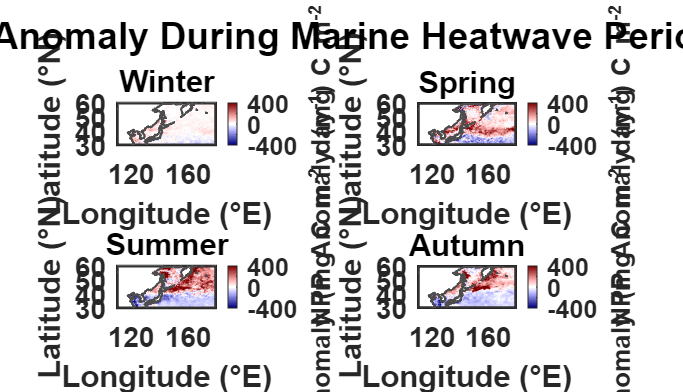


% 创建经纬度网格
[LON, LAT] = meshgrid(lon_region(1,:), lat_region(:,1));

% 设置绘图参数
font_size = 12;
title_font_size = 14;
colorbar_font_size = 11;

% 创建改进的红蓝色谱（确保0值为白色）
redblue_cmap = create_redblue_cmap_improved(64);

%% 图1: 四季热浪期NPP异常对比（冬季在左上角）
fig1 = figure('Position', [100, 100, 1400, 1000]);
set(fig1, 'Color', 'white', 'PaperPositionMode', 'auto');

% 冬季热浪期 - 左上角
subplot(2,2,1);
h1 = pcolor(LON, LAT, winter_hw_anom);
set(h1, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]);
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Winter', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

% 春季热浪期 - 右上角
subplot(2,2,2);
h2 = pcolor(LON, LAT, spring_hw_anom);
set(h2, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]);
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Spring', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

% 夏季热浪期 - 左下角
subplot(2,2,3);
h3 = pcolor(LON, LAT, summer_hw_anom);
set(h3, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]);
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Summer', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

% 秋季热浪期 - 右下角
subplot(2,2,4);
h4 = pcolor(LON, LAT, autumn_hw_anom);
set(h4, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]);
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Autumn', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

sgtitle('Seasonal NPP Anomaly During Marine Heatwave Periods (2015-2024)', ...
        'FontSize', 16, 'FontWeight', 'bold');

print(fig1, fullfile(output_dir, 'Figure7_Seasonal_MHW_NPP.png'), '-dpng', '-r300');

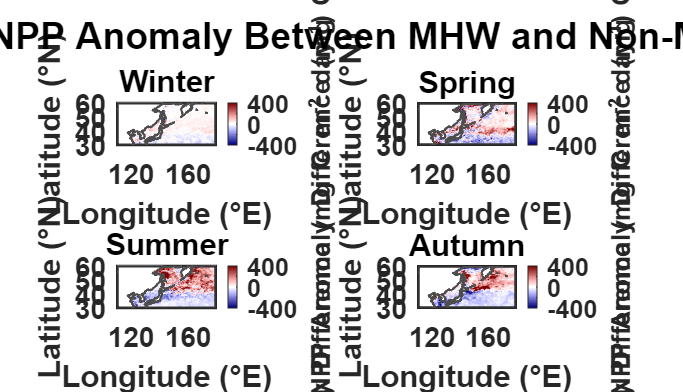

saveas(fig1, fullfile(output_dir, 'Figure7_Seasonal_MHW_NPP.fig'));

%% 图2: 四季热浪与非热浪期NPP差异（冬季在左上角）
fig2 = figure('Position', [100, 100, 1400, 1000]);
set(fig2, 'Color', 'white', 'PaperPositionMode', 'auto');

% 冬季差异 - 左上角
subplot(2,2,1);
h1 = pcolor(LON, LAT, winter_diff);
set(h1, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]); % 改为-400到400以保持一致
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly Difference (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Winter', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

% 春季差异 - 右上角
subplot(2,2,2);
h2 = pcolor(LON, LAT, spring_diff);
set(h2, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]); % 改为-400到400以保持一致
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly Difference (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Spring', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

% 夏季差异 - 左下角
subplot(2,2,3);
h3 = pcolor(LON, LAT, summer_diff);
set(h3, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]); % 改为-400到400以保持一致
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly Difference (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Summer', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

% 秋季差异 - 右下角
subplot(2,2,4);
h4 = pcolor(LON, LAT, autumn_diff);
set(h4, 'EdgeColor', 'none', 'FaceColor', 'flat');
colormap(gca, redblue_cmap);
caxis([-400, 400]); % 改为-400到400以保持一致
cbar = colorbar('eastoutside');
cbar.Label.String = 'NPP Anomaly Difference (mg C m^{-2} day^{-1})';
cbar.Label.FontSize = colorbar_font_size;
xlabel('Longitude (°E)', 'FontSize', font_size);
ylabel('Latitude (°N)', 'FontSize', font_size);
title('Autumn', 'FontSize', title_font_size, 'FontWeight', 'bold'); % 仅季节名称
add_white_land_coastline(lon_range, lat_range);
axis equal;
xlim(lon_range);
ylim(lat_range);
set(gca, 'TickDir', 'out', 'LineWidth', 0.8, 'FontSize', font_size, 'Color', 'white');

sgtitle('Seasonal Differences in NPP Anomaly Between MHW and Non-MHW Periods (2015-2024)', ...
        'FontSize', 16, 'FontWeight', 'bold');

print(fig2, fullfile(output_dir, 'Figure8_Seasonal_Differences.png'), '-dpng', '-r300');

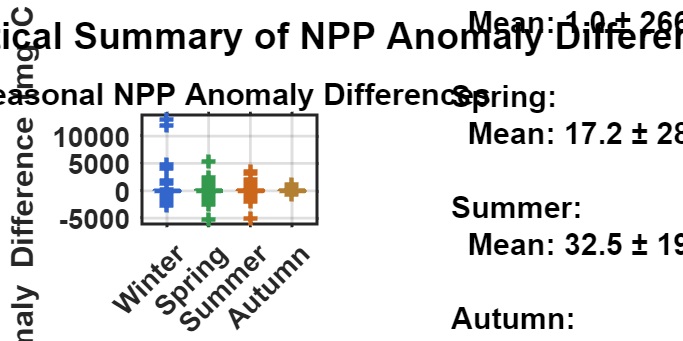

saveas(fig2, fullfile(output_dir, 'Figure8_Seasonal_Differences.fig'));

%% 图3: 四季统计摘要（保持原样，但更新为冬季在首位）
fig3 = figure('Position', [100, 100, 1200, 600]);
set(fig3, 'Color', 'white', 'PaperPositionMode', 'auto');

% 计算四季统计
seasonal_stats.winter_mean = nanmean(winter_diff(:));
seasonal_stats.spring_mean = nanmean(spring_diff(:));
seasonal_stats.summer_mean = nanmean(summer_diff(:));
seasonal_stats.autumn_mean = nanmean(autumn_diff(:));

seasonal_stats.winter_std = nanstd(winter_diff(:));
seasonal_stats.spring_std = nanstd(spring_diff(:));
seasonal_stats.summer_std = nanstd(summer_diff(:));
seasonal_stats.autumn_std = nanstd(autumn_diff(:));

% 子图1: 四季差异箱线图（冬季在首位）
subplot(1,2,1);
seasonal_data = [];
seasonal_labels = {};

% 收集四季数据（随机采样以避免内存问题），按冬季、春季、夏季、秋季顺序
winter_data = winter_diff(~isnan(winter_diff));
spring_data = spring_diff(~isnan(spring_diff));
summer_data = summer_diff(~isnan(summer_diff));
autumn_data = autumn_diff(~isnan(autumn_diff));

% 冬季
if length(winter_data) > 5000
    idx = randsample(length(winter_data), 5000);
    seasonal_data = [seasonal_data, winter_data(idx)];
else
    seasonal_data = [seasonal_data, winter_data];
end
seasonal_labels{end+1} = 'Winter';

% 春季
if length(spring_data) > 5000
    idx = randsample(length(spring_data), 5000);
    seasonal_data = [seasonal_data, spring_data(idx)];
else
    seasonal_data = [seasonal_data, spring_data];
end
seasonal_labels{end+1} = 'Spring';

% 夏季
if length(summer_data) > 5000
    idx = randsample(length(summer_data), 5000);
    seasonal_data = [seasonal_data, summer_data(idx)];
else
    seasonal_data = [seasonal_data, summer_data];
end
seasonal_labels{end+1} = 'Summer';

% 秋季
if length(autumn_data) > 5000
    idx = randsample(length(autumn_data), 5000);
    seasonal_data = [seasonal_data, autumn_data(idx)];
else
    seasonal_data = [seasonal_data, autumn_data];
end
seasonal_labels{end+1} = 'Autumn';

box_handle = boxplot(seasonal_data, seasonal_labels, ...
                    'Colors', [0.2 0.4 0.8; 0.2 0.6 0.3; 0.8 0.4 0.1; 0.7 0.5 0.2], ...
                    'Widths', 0.6, 'Symbol', '+');
set(box_handle, {'LineWidth'}, {2});
ylabel('NPP Anomaly Difference (mg C m^{-2} day^{-1})', 'FontSize', font_size);
title('Seasonal NPP Anomaly Differences', 'FontSize', title_font_size, 'FontWeight', 'bold');
set(gca, 'FontSize', font_size, 'TickDir', 'out');
grid on;

% 子图2: 四季统计表格（冬季在首位）
subplot(1,2,2);
seasonal_summary_text = {
    sprintf('Seasonal Statistical Summary')
    sprintf('')
    sprintf('Winter:')
    sprintf('  Mean: %.1f ± %.1f', seasonal_stats.winter_mean, seasonal_stats.winter_std)
    sprintf('')
    sprintf('Spring:')
    sprintf('  Mean: %.1f ± %.1f', seasonal_stats.spring_mean, seasonal_stats.spring_std)
    sprintf('')
    sprintf('Summer:')
    sprintf('  Mean: %.1f ± %.1f', seasonal_stats.summer_mean, seasonal_stats.summer_std)
    sprintf('')
    sprintf('Autumn:')
    sprintf('  Mean: %.1f ± %.1f', seasonal_stats.autumn_mean, seasonal_stats.autumn_std)
    sprintf('')
    sprintf('Annual Mean: %.1f', nanmean(diff_anom(:)))
};

text(0.05, 0.5, seasonal_summary_text, 'FontSize', font_size+1, ...
     'VerticalAlignment', 'middle', 'Units', 'normalized', ...
     'FontWeight', 'bold', 'FontName', 'Arial');
axis off;

sgtitle('Seasonal Statistical Summary of NPP Anomaly Differences (2015-2024)', ...
        'FontSize', 16, 'FontWeight', 'bold');

print(fig3, fullfile(output_dir, 'Figure9_Seasonal_Statistics.png'), '-dpng', '-r300');

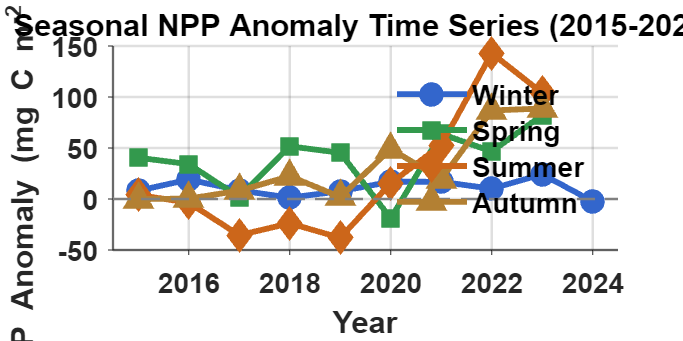

saveas(fig3, fullfile(output_dir, 'Figure9_Seasonal_Statistics.fig'));

%% 图4: 四季NPP异常时间序列图
fig4 = figure('Position', [100, 100, 1200, 600]);
set(fig4, 'Color', 'white', 'PaperPositionMode', 'auto');

% 定义季节颜色
season_colors = [0.2 0.4 0.8;  % 冬季 - 蓝色
                 0.2 0.6 0.3;  % 春季 - 绿色
                 0.8 0.4 0.1;  % 夏季 - 橙色
                 0.7 0.5 0.2]; % 秋季 - 棕色

% 绘制时间序列
hold on;

% 冬季时间序列
winter_plot = plot(seasonal_ts_data.years, seasonal_ts_data.winter, '-o', ...
                  'Color', season_colors(1,:), 'LineWidth', 2.5, ...
                  'MarkerSize', 8, 'MarkerFaceColor', season_colors(1,:));

% 春季时间序列
spring_plot = plot(seasonal_ts_data.years, seasonal_ts_data.spring, '-s', ...
                  'Color', season_colors(2,:), 'LineWidth', 2.5, ...
                  'MarkerSize', 8, 'MarkerFaceColor', season_colors(2,:));

% 夏季时间序列
summer_plot = plot(seasonal_ts_data.years, seasonal_ts_data.summer, '-d', ...
                  'Color', season_colors(3,:), 'LineWidth', 2.5, ...
                  'MarkerSize', 8, 'MarkerFaceColor', season_colors(3,:));

% 秋季时间序列
autumn_plot = plot(seasonal_ts_data.years, seasonal_ts_data.autumn, '-^', ...
                  'Color', season_colors(4,:), 'LineWidth', 2.5, ...
                  'MarkerSize', 8, 'MarkerFaceColor', season_colors(4,:));

% 添加零线
plot([min(seasonal_ts_data.years)-0.5, max(seasonal_ts_data.years)+0.5], [0, 0], ...
     'k--', 'LineWidth', 1, 'Color', [0.5 0.5 0.5]);

% 设置图形属性
xlabel('Year', 'FontSize', font_size+1);
ylabel('NPP Anomaly (mg C m^{-2} day^{-1})', 'FontSize', font_size+1);
title('Seasonal NPP Anomaly Time Series (2015-2024)', ...
      'FontSize', title_font_size+2, 'FontWeight', 'bold');

% 设置坐标轴
xlim([min(seasonal_ts_data.years)-0.5, max(seasonal_ts_data.years)+0.5]);
grid on;
set(gca, 'FontSize', font_size, 'TickDir', 'out', 'LineWidth', 1.0);

% 添加图例
legend([winter_plot, spring_plot, summer_plot, autumn_plot], ...
       {'Winter', 'Spring', 'Summer', 'Autumn'}, ...
       'Location', 'best', 'FontSize', font_size, 'Box', 'off');

% 添加趋势线
% 计算各季节趋势
for i = 1:4
    switch i
        case 1
            data = seasonal_ts_data.winter;
            color = season_colors(1,:);
        case 2
            data = seasonal_ts_data.spring;
            color = season_colors(2,:);
        case 3
            data = seasonal_ts_data.summer;
            color = season_colors(3,:);
        case 4
            data = seasonal_ts_data.autumn;
            color = season_colors(4,:);
    end
    
    % 移除NaN值
    valid_idx = ~isnan(data);
    if sum(valid_idx) > 1
        x_trend = seasonal_ts_data.years(valid_idx);
        y_trend = data(valid_idx);
        
        % 计算线性趋势
        p = polyfit(x_trend, y_trend, 1);
        trend_line = polyval(p, x_trend);
        
       
    end
end

print(fig4, fullfile(output_dir, 'Figure10_Seasonal_Time_Series.png'), '-dpng', '-r300');

saveas(fig4, fullfile(output_dir, 'Figure10_Seasonal_Time_Series.fig'));

%% 第九步：保存结果
fprintf('保存分析结果...\n');

保存分析结果...



% 保存空间分布数据
spatial_data.lon = lon_region(1,:);
spatial_data.lat = lat_region(:,1);
spatial_data.mean_hw_anom = mean_hw_anom;
spatial_data.mean_non_hw_anom = mean_non_hw_anom;
spatial_data.diff_anom = diff_anom;
spatial_data.hw_frequency = hw_frequency;


% 保存时间序列数据
time_series_data = seasonal_ts_data;

save(fullfile(output_dir, 'spatial_analysis_data.mat'), 'spatial_data', 'seasonal_data', 'seasonal_stats', 'time_series_data');

fprintf('分析完成！所有结果已保存到目录: %s\n', output_dir);

分析完成！所有结果已保存到目录: npp_heatwave_analysis


fprintf('生成的四季分析图:\n');

生成的四季分析图:


fprintf('  Figure7: 四季热浪期NPP异常对比 (4个子图)\n');

  Figure7: 四季热浪期NPP异常对比 (4个子图)


fprintf('  Figure8: 四季热浪与非热浪期NPP差异 (4个子图)\n');

  Figure8: 四季热浪与非热浪期NPP差异 (4个子图)


fprintf('  Figure9: 四季统计摘要 (箱线图和统计表格)\n');

  Figure9: 四季统计摘要 (箱线图和统计表格)


fprintf('  Figure10: 四季NPP异常时间序列图\n');

  Figure10: 四季NPP异常时间序列图


fprintf('季节排列顺序: 冬季在左上角，范围统一为-400到400，仅显示季节名称\n');

季节排列顺序: 冬季在左上角，范围统一为-400到400，仅显示季节名称



%% 辅助函数定义
%% 第十步：统计分析 - 15-24年NPP变化及热浪/非热浪差异
fprintf('进行统计分析...\n');

进行统计分析...



% 1. 计算2015-2024年相对于基准期的总体NPP变化
fprintf('计算2015-2024年相对于基准期的总体NPP变化...\n');

计算2015-2024年相对于基准期的总体NPP变化...



% 计算分析期（2015-2024）的平均NPP
analysis_mean_npp = nanmean(npp_analysis_data, 3);

% 计算整个基准期的平均NPP（所有年积日的平均）
baseline_mean_all = nanmean(baseline_climatology, 3);

% 计算相对于基准期的绝对变化和相对变化
npp_absolute_change = analysis_mean_npp - baseline_mean_all;
npp_relative_change = (npp_absolute_change ./ baseline_mean_all) * 100;

% 处理可能的无穷大值（由于除以接近零的值）
npp_relative_change(isinf(npp_relative_change)) = NaN;
npp_relative_change(abs(npp_relative_change) > 1000) = NaN; % 移除极端值

% 计算整个区域的统计
overall_absolute_change = nanmean(npp_absolute_change(:));
overall_relative_change = nanmean(npp_relative_change(:));

% 2. 计算热浪期vs非热浪期的统计差异
fprintf('计算热浪期vs非热浪期的统计差异...\n');

计算热浪期vs非热浪期的统计差异...



% 计算热浪期和非热浪期的平均NPP（不是异常，而是实际值）
hw_actual_npp = zeros(nlat_region, nlon_region, 'single');
non_hw_actual_npp = zeros(nlat_region, nlon_region, 'single');
hw_actual_count = zeros(nlat_region, nlon_region, 'single');
non_hw_actual_count = zeros(nlat_region, nlon_region, 'single');

for t_idx = 1:n_times_npp
    current_npp = npp_analysis_data(:, :, t_idx);
    current_hw_mask = squeeze(hw_mask_npp_grid(t_idx, :, :));
    
    for i_lat = 1:nlat_region
        for i_lon = 1:nlon_region
            npp_val = current_npp(i_lat, i_lon);
            
            if isnan(npp_val)
                continue;
            end
            
            if current_hw_mask(i_lat, i_lon)
                hw_actual_npp(i_lat, i_lon) = hw_actual_npp(i_lat, i_lon) + npp_val;
                hw_actual_count(i_lat, i_lon) = hw_actual_count(i_lat, i_lon) + 1;
            else
                non_hw_actual_npp(i_lat, i_lon) = non_hw_actual_npp(i_lat, i_lon) + npp_val;
                non_hw_actual_count(i_lat, i_lon) = non_hw_actual_count(i_lat, i_lon) + 1;
            end
        end
    end
end

% 计算平均实际NPP
mean_hw_actual = hw_actual_npp ./ max(hw_actual_count, 1);
mean_non_hw_actual = non_hw_actual_npp ./ max(non_hw_actual_count, 1);
actual_diff = mean_hw_actual - mean_non_hw_actual;

% 处理NaN值
mean_hw_actual(isnan(mean_hw_actual)) = 0;
mean_non_hw_actual(isnan(mean_non_hw_actual)) = 0;
actual_diff(isnan(actual_diff)) = 0;

% 计算相对变化百分比
relative_diff_percent = (actual_diff ./ mean_non_hw_actual) * 100;
relative_diff_percent(isinf(relative_diff_percent)) = NaN;
relative_diff_percent(abs(relative_diff_percent) > 1000) = NaN; % 移除极端值

% 3. 计算区域平均统计
fprintf('计算区域平均统计...\n');

计算区域平均统计...



% 相对于基准期的变化统计
region_absolute_change = nanmean(npp_absolute_change(:));
region_relative_change = nanmean(npp_relative_change(:));

% 热浪vs非热浪的实际NPP差异统计
region_hw_npp = nanmean(mean_hw_actual(:));
region_non_hw_npp = nanmean(mean_non_hw_actual(:));
region_actual_diff = nanmean(actual_diff(:));
region_relative_diff = nanmean(relative_diff_percent(:));

% 4. 按季节统计热浪vs非热浪差异
fprintf('按季节统计热浪vs非热浪差异...\n');

按季节统计热浪vs非热浪差异...



seasonal_actual_stats = struct();
season_names = {'Winter', 'Spring', 'Summer', 'Autumn'};

for season_idx = 1:4
    switch season_idx
        case 1
            diff_data = winter_diff;
            season_name = 'Winter';
        case 2
            diff_data = spring_diff;
            season_name = 'Spring';
        case 3
            diff_data = summer_diff;
            season_name = 'Summer';
        case 4
            diff_data = autumn_diff;
            season_name = 'Autumn';
    end
    
    seasonal_actual_stats.(season_name).mean_diff = nanmean(diff_data(:));
    seasonal_actual_stats.(season_name).std_diff = nanstd(diff_data(:));
    valid_data = diff_data(~isnan(diff_data));
    if ~isempty(valid_data)
        seasonal_actual_stats.(season_name).positive_percent = sum(valid_data > 0) / length(valid_data) * 100;
        seasonal_actual_stats.(season_name).negative_percent = sum(valid_data < 0) / length(valid_data) * 100;
    else
        seasonal_actual_stats.(season_name).positive_percent = 0;
        seasonal_actual_stats.(season_name).negative_percent = 0;
    end
end

% 5. 生成统计分析报告
fprintf('生成统计分析报告...\n');

生成统计分析报告...


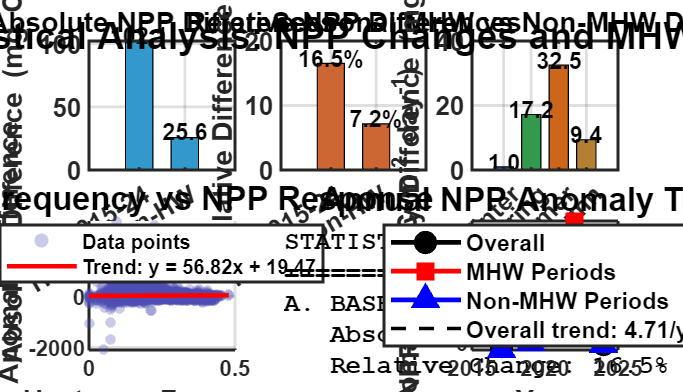


% 创建统计分析图
fig_stats = figure('Position', [100, 100, 1400, 1000]);
set(fig_stats, 'Color', 'white', 'PaperPositionMode', 'auto');

% 子图1: 总体变化统计
subplot(2,3,1);

% 创建柱状图显示关键统计
categories = {'Baseline to 2015-24', 'HW vs Non-HW'};
absolute_values = [region_absolute_change, region_actual_diff];
relative_values = [region_relative_change, region_relative_diff];

bar(1:2, absolute_values, 0.6, 'FaceColor', [0.2 0.6 0.8]);
ylabel('Absolute Difference (mg C m^{-2} day^{-1})', 'FontSize', 12);
title('Absolute NPP Differences', 'FontSize', 14, 'FontWeight', 'bold');
set(gca, 'XTickLabel', categories, 'FontSize', 11);
grid on;

% 在柱子上添加数值标签
for i = 1:2
    text(i, absolute_values(i) + sign(absolute_values(i))*max(abs(absolute_values))*0.05, ...
        sprintf('%.1f', absolute_values(i)), 'HorizontalAlignment', 'center', ...
        'FontSize', 10, 'FontWeight', 'bold');
end

% 子图2: 相对变化统计
subplot(2,3,2);
bar(1:2, relative_values, 0.6, 'FaceColor', [0.8 0.4 0.2]);
ylabel('Relative Difference (%)', 'FontSize', 12);
title('Relative NPP Differences', 'FontSize', 14, 'FontWeight', 'bold');
set(gca, 'XTickLabel', categories, 'FontSize', 11);
grid on;

% 在柱子上添加数值标签
for i = 1:2
    text(i, relative_values(i) + sign(relative_values(i))*max(abs(relative_values))*0.05, ...
        sprintf('%.1f%%', relative_values(i)), 'HorizontalAlignment', 'center', ...
        'FontSize', 10, 'FontWeight', 'bold');
end

% 子图3: 季节差异统计
subplot(2,3,3);
season_means = [seasonal_actual_stats.Winter.mean_diff, ...
                seasonal_actual_stats.Spring.mean_diff, ...
                seasonal_actual_stats.Summer.mean_diff, ...
                seasonal_actual_stats.Autumn.mean_diff];

season_colors = [0.2 0.4 0.8; 0.2 0.6 0.3; 0.8 0.4 0.1; 0.7 0.5 0.2];
h = bar(1:4, season_means, 0.7, 'FaceColor', 'flat');
h.CData = season_colors;
ylabel('NPP Anomaly Difference (mg C m^{-2} day^{-1})', 'FontSize', 12);
title('Seasonal MHW vs Non-MHW Differences', 'FontSize', 14, 'FontWeight', 'bold');
set(gca, 'XTickLabel', {'Winter', 'Spring', 'Summer', 'Autumn'}, 'FontSize', 11);
grid on;

% 在柱子上添加数值标签
for i = 1:4
    text(i, season_means(i) + sign(season_means(i))*max(abs(season_means))*0.05, ...
        sprintf('%.1f', season_means(i)), 'HorizontalAlignment', 'center', ...
        'FontSize', 10, 'FontWeight', 'bold');
end

% 子图4: 热浪频率与NPP响应关系
subplot(2,3,4);

% 计算每个网格点的热浪频率和平均NPP异常差异的关系
hw_freq_flat = hw_frequency(:);
diff_flat = diff_anom(:);

% 移除NaN值
valid_idx = ~isnan(hw_freq_flat) & ~isnan(diff_flat);
hw_freq_valid = hw_freq_flat(valid_idx);
diff_valid = diff_flat(valid_idx);

% 如果数据量太大，随机采样
if length(hw_freq_valid) > 10000
    sample_idx = randsample(length(hw_freq_valid), 10000);
    hw_freq_plot = hw_freq_valid(sample_idx);
    diff_plot = diff_valid(sample_idx);
else
    hw_freq_plot = hw_freq_valid;
    diff_plot = diff_valid;
end

if ~isempty(hw_freq_plot)
    scatter(hw_freq_plot, diff_plot, 20, 'filled', 'MarkerFaceAlpha', 0.3, ...
            'MarkerFaceColor', [0.3 0.3 0.7]);
    xlabel('Heatwave Frequency', 'FontSize', 12);
    ylabel('NPP Anomaly Difference', 'FontSize', 12);
    title('MHW Frequency vs NPP Response', 'FontSize', 14, 'FontWeight', 'bold');
    grid on;

    % 添加趋势线
    if length(hw_freq_plot) > 10
        p = polyfit(hw_freq_plot, diff_plot, 1);
        trend_x = [min(hw_freq_plot), max(hw_freq_plot)];
        trend_y = polyval(p, trend_x);
        hold on;
        plot(trend_x, trend_y, 'r-', 'LineWidth', 2);
        legend('Data points', sprintf('Trend: y = %.2fx + %.2f', p(1), p(2)), ...
               'Location', 'best');
    end
else
    text(0.5, 0.5, 'No valid data for correlation analysis', ...
         'HorizontalAlignment', 'center', 'FontSize', 12);
    title('MHW Frequency vs NPP Response', 'FontSize', 14, 'FontWeight', 'bold');
end

% 子图5: 详细统计摘要
subplot(2,3,5);

% 创建详细的统计文本
stats_text = {
    'STATISTICAL SUMMARY (2015-2024)'
    '================================'
    sprintf('A. BASELINE (2005-2014) to ANALYSIS PERIOD')
    sprintf('   Absolute Change: %.2f mg C/m²/day', region_absolute_change)
    sprintf('   Relative Change: %.1f%%', region_relative_change)
    sprintf('')
    sprintf('B. MHW vs NON-MHW PERIODS')
    sprintf('   MHW NPP: %.1f mg C/m²/day', region_hw_npp)
    sprintf('   Non-MHW NPP: %.1f mg C/m²/day', region_non_hw_npp)
    sprintf('   Absolute Difference: %.2f mg C/m²/day', region_actual_diff)
    sprintf('   Relative Difference: %.1f%%', region_relative_diff)
    sprintf('')
    sprintf('C. SEASONAL MHW IMPACTS')
    sprintf('   Winter:  %+6.1f mg C/m²/day', seasonal_actual_stats.Winter.mean_diff)
    sprintf('   Spring:  %+6.1f mg C/m²/day', seasonal_actual_stats.Spring.mean_diff)
    sprintf('   Summer:  %+6.1f mg C/m²/day', seasonal_actual_stats.Summer.mean_diff)
    sprintf('   Autumn:  %+6.1f mg C/m²/day', seasonal_actual_stats.Autumn.mean_diff)
    sprintf('')
    sprintf('D. SPATIAL PATTERNS')
};

% 计算空间模式统计
diff_anom_flat = diff_anom(:);
valid_diff = diff_anom_flat(~isnan(diff_anom_flat));
if ~isempty(valid_diff)
    positive_percent = sum(valid_diff > 0) / length(valid_diff) * 100;
    negative_percent = sum(valid_diff < 0) / length(valid_diff) * 100;
    no_change_percent = sum(abs(valid_diff) < 10) / length(valid_diff) * 100;
    
    stats_text{end+1} = sprintf('   Positive NPP Response: %.1f%% of area', positive_percent);
    stats_text{end+1} = sprintf('   Negative NPP Response: %.1f%% of area', negative_percent);
    stats_text{end+1} = sprintf('   No Significant Change: %.1f%% of area', no_change_percent);
else
    stats_text{end+1} = '   No valid spatial data available';
end

text(0.02, 0.98, stats_text, 'FontSize', 11, 'VerticalAlignment', 'top', ...
     'Units', 'normalized', 'FontName', 'Courier New', 'FontWeight', 'bold');
axis off;

% 子图6: 年度趋势分析
subplot(2,3,6);

% 计算年度平均NPP异常
annual_anomaly = zeros(length(unique_selected_years), 1);
annual_hw_anomaly = zeros(length(unique_selected_years), 1);
annual_non_hw_anomaly = zeros(length(unique_selected_years), 1);

for i = 1:length(unique_selected_years)
    year = unique_selected_years(i);
    year_mask = (selected_years == year);
    
    % 年度平均异常
    annual_anomaly(i) = nanmean(spatial_mean_anomaly(year_mask));
    
    % 热浪期和非热浪期异常
    year_hw_anomalies = [];
    year_non_hw_anomalies = [];
    
    for t = find(year_mask)'
        current_anomaly_flat = npp_anomaly(:, :, t);
        current_hw_mask_flat = squeeze(hw_mask_npp_grid(t, :, :));
        
        hw_anomalies = current_anomaly_flat(current_hw_mask_flat & ~isnan(current_anomaly_flat));
        non_hw_anomalies = current_anomaly_flat(~current_hw_mask_flat & ~isnan(current_anomaly_flat));
        
        year_hw_anomalies = [year_hw_anomalies; hw_anomalies(:)];
        year_non_hw_anomalies = [year_non_hw_anomalies; non_hw_anomalies(:)];
    end
    
    if ~isempty(year_hw_anomalies)
        annual_hw_anomaly(i) = nanmean(year_hw_anomalies);
    else
        annual_hw_anomaly(i) = NaN;
    end
    
    if ~isempty(year_non_hw_anomalies)
        annual_non_hw_anomaly(i) = nanmean(year_non_hw_anomalies);
    else
        annual_non_hw_anomaly(i) = NaN;
    end
end

% 绘制年度趋势
plot(unique_selected_years, annual_anomaly, 'k-o', 'LineWidth', 2, ...
     'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Overall');
hold on;
plot(unique_selected_years, annual_hw_anomaly, 'r-s', 'LineWidth', 2, ...
     'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'MHW Periods');
plot(unique_selected_years, annual_non_hw_anomaly, 'b-^', 'LineWidth', 2, ...
     'MarkerSize', 8, 'MarkerFaceColor', 'b', 'DisplayName', 'Non-MHW Periods');

xlabel('Year', 'FontSize', 12);
ylabel('NPP Anomaly (mg C m^{-2} day^{-1})', 'FontSize', 12);
title('Annual NPP Anomaly Trends', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 10);
grid on;

% 添加趋势线
if sum(~isnan(annual_anomaly)) > 1
    valid_years = unique_selected_years(~isnan(annual_anomaly));
    valid_anomaly = annual_anomaly(~isnan(annual_anomaly));
    p_overall = polyfit(valid_years, valid_anomaly, 1);
    trend_overall = polyval(p_overall, unique_selected_years);
    plot(unique_selected_years, trend_overall, 'k--', 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Overall trend: %.2f/yr', p_overall(1)));
end

sgtitle('Comprehensive Statistical Analysis: NPP Changes and MHW Impacts (2015-2024)', ...
        'FontSize', 16, 'FontWeight', 'bold');

print(fig_stats, fullfile(output_dir, 'Figure11_Statistical_Analysis.png'), '-dpng', '-r300');

saveas(fig_stats, fullfile(output_dir, 'Figure11_Statistical_Analysis.fig'));

% 6. 保存统计结果到文本文件
fprintf('保存统计结果到文本文件...\n');

保存统计结果到文本文件...



stats_filename = fullfile(output_dir, 'statistical_analysis_report.txt');
fid = fopen(stats_filename, 'w');

fprintf(fid, 'NPP AND MARINE HEATWAVE STATISTICAL ANALYSIS REPORT\n');
fprintf(fid, '===================================================\n\n');
fprintf(fid, 'Analysis Period: 2015-2024\n');
fprintf(fid, 'Baseline Period: 2005-2014\n');
fprintf(fid, 'Study Region: %.1f-%.1f°E, %.1f-%.1f°N\n\n', ...
        lon_range(1), lon_range(2), lat_range(1), lat_range(2));

fprintf(fid, 'OVERALL CHANGES (2015-2024 vs 2005-2014)\n');
fprintf(fid, '----------------------------------------\n');
fprintf(fid, 'Absolute NPP Change: %+.2f mg C/m²/day\n', region_absolute_change);
fprintf(fid, 'Relative NPP Change: %+.1f%%\n\n', region_relative_change);

fprintf(fid, 'MHW vs NON-MHW COMPARISON (2015-2024)\n');
fprintf(fid, '-------------------------------------\n');
fprintf(fid, 'Average NPP during MHW periods:     %.1f mg C/m²/day\n', region_hw_npp);
fprintf(fid, 'Average NPP during non-MHW periods: %.1f mg C/m²/day\n', region_non_hw_npp);
fprintf(fid, 'Absolute difference (MHW - Non-MHW): %+.2f mg C/m²/day\n', region_actual_diff);
fprintf(fid, 'Relative difference: %+.1f%%\n\n', region_relative_diff);

fprintf(fid, 'SEASONAL MHW IMPACTS\n');
fprintf(fid, '--------------------\n');
for i = 1:4
    season_name = season_names{i};
    stats = seasonal_actual_stats.(season_name);
    fprintf(fid, '%s:\n', season_name);
    fprintf(fid, '  Mean NPP difference: %+6.1f mg C/m²/day\n', stats.mean_diff);
    fprintf(fid, '  Standard deviation:  %6.1f mg C/m²/day\n', stats.std_diff);
    fprintf(fid, '  Positive areas:      %6.1f%%\n', stats.positive_percent);
    fprintf(fid, '  Negative areas:      %6.1f%%\n\n', stats.negative_percent);
end

fprintf(fid, 'SPATIAL DISTRIBUTION\n');
fprintf(fid, '--------------------\n');
if ~isempty(valid_diff)
    fprintf(fid, 'Areas with positive NPP response to MHW: %.1f%%\n', positive_percent);
    fprintf(fid, 'Areas with negative NPP response to MHW: %.1f%%\n', negative_percent);
    fprintf(fid, 'Areas with no significant change: %.1f%%\n\n', no_change_percent);
else
    fprintf(fid, 'No valid spatial data available\n\n');
end

fprintf(fid, 'TREND ANALYSIS\n');
fprintf(fid, '--------------\n');
if sum(~isnan(annual_anomaly)) > 1
    valid_years = unique_selected_years(~isnan(annual_anomaly));
    valid_anomaly = annual_anomaly(~isnan(annual_anomaly));
    p = polyfit(valid_years, valid_anomaly, 1);
    fprintf(fid, 'Overall NPP anomaly trend: %+.3f mg C/m²/day per year\n', p(1));
    fprintf(fid, 'Trend significance: ');
    if abs(p(1)) > 0.5
        fprintf(fid, 'STRONG\n');
    elseif abs(p(1)) > 0.1
        fprintf(fid, 'MODERATE\n');
    else
        fprintf(fid, 'WEAK\n');
    end
else
    fprintf(fid, 'Insufficient data for trend analysis\n');
end

fclose(fid);

% 7. 在控制台输出关键结果
fprintf('\n');
fprintf('===================================================\n');

fprintf('KEY STATISTICAL RESULTS (2015-2024)\n');

KEY STATISTICAL RESULTS (2015-2024)


fprintf('===================================================\n');

fprintf('1. Overall NPP Change vs Baseline (2005-2014):\n');

1. Overall NPP Change vs Baseline (2005-2014):


fprintf('   Absolute: %+.2f mg C/m²/day\n', region_absolute_change);

   Absolute: +102.15 mg C/m²/day


fprintf('   Relative: %+.1f%%\n\n', region_relative_change);

   Relative: +16.5%




fprintf('2. MHW vs Non-MHW Periods:\n');

2. MHW vs Non-MHW Periods:


fprintf('   MHW NPP: %.1f mg C/m²/day\n', region_hw_npp);

   MHW NPP: 446.2 mg C/m²/day


fprintf('   Non-MHW NPP: %.1f mg C/m²/day\n', region_non_hw_npp);

   Non-MHW NPP: 420.5 mg C/m²/day


fprintf('   Difference: %+.2f mg C/m²/day (%+.1f%%)\n\n', ...
        region_actual_diff, region_relative_diff);

   Difference: +25.64 mg C/m²/day (+7.2%)




fprintf('3. Seasonal MHW Impacts:\n');

3. Seasonal MHW Impacts:


for i = 1:4
    season_name = season_names{i};
    stats = seasonal_actual_stats.(season_name);
    fprintf('   %s: %+6.1f mg C/m²/day\n', season_name, stats.mean_diff);
end

   Winter:   +1.0 mg C/m²/day
   Spring:  +17.2 mg C/m²/day
   Summer:  +32.5 mg C/m²/day
   Autumn:   +9.4 mg C/m²/day


fprintf('\n');

fprintf('4. Spatial Response Patterns:\n');

4. Spatial Response Patterns:


if ~isempty(valid_diff)
    fprintf('   Positive response: %.1f%% of study area\n', positive_percent);
    fprintf('   Negative response: %.1f%% of study area\n', negative_percent);
else
    fprintf('   No valid spatial data available\n');
end

   Positive response: 35.5% of study area


   Negative response: 27.5% of study area


fprintf('\n');

fprintf('Detailed report saved to: %s\n', stats_filename);

Detailed report saved to: npp_heatwave_analysis\statistical_analysis_report.txt


fprintf('Statistical figures saved as: Figure11_Statistical_Analysis.png\n');

Statistical figures saved as: Figure11_Statistical_Analysis.png



%% 更新保存的数据以包含统计结果
fprintf('更新保存的数据以包含统计结果...\n');

更新保存的数据以包含统计结果...



% 添加到现有的保存数据中
statistical_results.overall_absolute_change = region_absolute_change;
statistical_results.overall_relative_change = region_relative_change;
statistical_results.hw_vs_non_hw_absolute = region_actual_diff;
statistical_results.hw_vs_non_hw_relative = region_relative_diff;
statistical_results.seasonal_stats = seasonal_actual_stats;
statistical_results.annual_trends.anomaly = annual_anomaly;
statistical_results.annual_trends.hw_anomaly = annual_hw_anomaly;
statistical_results.annual_trends.non_hw_anomaly = annual_non_hw_anomaly;

% 重新保存包含统计结果的数据
save(fullfile(output_dir, 'spatial_analysis_data.mat'), ...
     'spatial_data', 'seasonal_data', 'seasonal_stats', 'time_series_data', ...
     'statistical_results', '-append');

fprintf('统计分析完成！\n');

统计分析完成！


function cmap = create_redblue_cmap_improved(n)
    % 创建改进的红蓝色谱，确保0值为白色
    if nargin < 1
        n = 64;
    end
    
    % 确保n是偶数
    if mod(n, 2) ~= 0
        n = n + 1;
    end
    
    half = n/2;
    cmap = zeros(n, 3);
    
    % 蓝色部分 (从深蓝到白色)
    for i = 1:half
        ratio = (i-1)/(half-1);
        % 从深蓝到浅蓝到白色
        if ratio < 0.7
            % 深蓝到浅蓝
            blue_ratio = ratio/0.7;
            cmap(i, 1) = 0.0 * (1-blue_ratio) + 0.7 * blue_ratio;
            cmap(i, 2) = 0.0 * (1-blue_ratio) + 0.7 * blue_ratio;
            cmap(i, 3) = 0.5 * (1-blue_ratio) + 1.0 * blue_ratio;
        else
            % 浅蓝到白色
            white_ratio = (ratio-0.7)/0.3;
            cmap(i, 1) = 0.7 * (1-white_ratio) + 1.0 * white_ratio;
            cmap(i, 2) = 0.7 * (1-white_ratio) + 1.0 * white_ratio;
            cmap(i, 3) = 1.0;
        end
    end
    
    % 红色部分 (从白色到深红)
    for i = (half+1):n
        ratio = (i-half-1)/(half-1);
        % 从白色到浅红到深红
        if ratio < 0.3
            % 白色到浅红
            red_ratio = ratio/0.3;
            cmap(i, 1) = 1.0;
            cmap(i, 2) = 1.0 * (1-red_ratio) + 0.7 * red_ratio;
            cmap(i, 3) = 1.0 * (1-red_ratio) + 0.7 * red_ratio;
        else
            % 浅红到深红
            dark_ratio = (ratio-0.3)/0.7;
            cmap(i, 1) = 1.0 * (1-dark_ratio) + 0.5 * dark_ratio;
            cmap(i, 2) = 0.7 * (1-dark_ratio) + 0.0 * dark_ratio;
            cmap(i, 3) = 0.7 * (1-dark_ratio) + 0.0 * dark_ratio;
        end
    end
end

function add_white_land_coastline(lon_range, lat_range)
    % 添加白色陆地海岸线
    hold on;
    
    % 首先绘制区域边界
    plot([lon_range(1) lon_range(2) lon_range(2) lon_range(1) lon_range(1)], ...
         [lat_range(1) lat_range(1) lat_range(2) lat_range(2) lat_range(1)], ...
         'k-', 'LineWidth', 1.5, 'Color', [0.2 0.2 0.2]);
    
    % 尝试加载和绘制海岸线
    try
        % 检查海岸线数据是否已加载
        if ~exist('coastlon', 'var') || ~exist('coastlat', 'var')
            if exist('coastlines.mat', 'file')
                coast_data = load('coastlines.mat');
                coastlon = coast_data.coastlon;
                coastlat = coast_data.coastlat;
            else
                % 如果找不到coastlines.mat，创建一个简单的海岸线
                fprintf('Using simple coastline approximation\n');
                return;
            end
        end
        
        if exist('coastlon', 'var') && exist('coastlat', 'var')
            % 创建海岸线的副本进行处理
            coastlon_clean = coastlon;
            coastlat_clean = coastlat;
            
            % 找出大的跳跃（可能表示跨区域连接）
            dx = [0; diff(coastlon)];
            dy = [0; diff(coastlat)];
            large_jumps = (abs(dx) > 10) | (abs(dy) > 10);
            
            % 在大跳跃处插入NaN以断开线条
            coastlon_clean(large_jumps) = NaN;
            coastlat_clean(large_jumps) = NaN;
            
            % 绘制海岸线 - 使用黑色线条
            plot(coastlon_clean, coastlat_clean, ...
                 'k-', 'LineWidth', 1.0, 'Color', [0.3 0.3 0.3]);
        end
        
    catch ME
        % 如果海岸线绘制失败，只保留边界框
        fprintf('Coastline plotting failed, using boundary only: %s\n', ME.message);
    end
end